nx = [0:100];
x = sin(2*pi*nx/50) + sin(20*pi*nx/50);
freq = [0:1/512:1];
fx=fft (x,1024);
fxmag = abs(fx(1:513));

h=0.1*ones(1,10);
nh = [0:9];

y = conv(x, h, 'same')

y =     0.1812    0.3447    0.4806    0.5062    0.5016    0.5967    0.6824    0.7573    0.8203    0.8704    0.9067    0.9287    0.9361    0.9287    0.9067    0.8704    0.8203    0.7573    0.6824    0.5967    0.5016    0.3986    0.2893    0.1754    0.0588   -0.0588   -0.1754   -0.2893   -0.3986   -0.5016   -0.5967   -0.6824   -0.7573   -0.8203   -0.8704   -0.9067   -0.9287   -0.9361   -0.9287   -0.9067   -0.8704   -0.8203   -0.7573   -0.6824   -0.5967   -0.5016   -0.3986   -0.2893   -0.1754   -0.0588


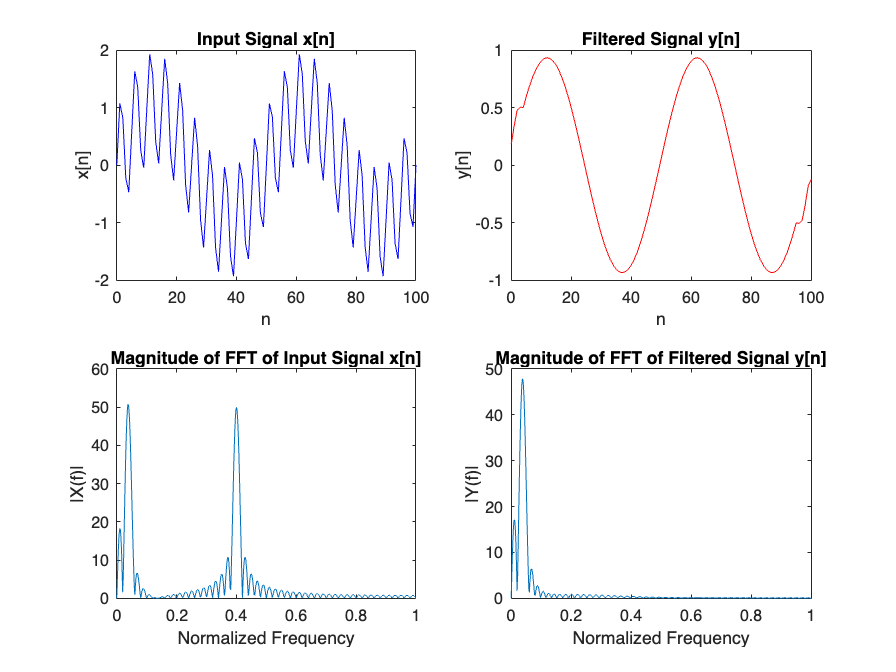

fy = fft(y, 1024);
fymag = abs(fy(1:513));  

% Time-domain plots
figure;
subplot(2,2,1);
plot(nx, x, 'b', 'DisplayName', 'Input Signal x[n]');
title('Input Signal x[n]');
xlabel('n');
ylabel('x[n]');

subplot(2,2,2);
plot(nx, y, 'r', 'DisplayName', 'Filtered Signal y[n]');
title('Filtered Signal y[n]');
xlabel('n');
ylabel('y[n]');

% Frequency-domain plots
subplot(2,2,3);
plot(freq, fxmag);
title('Magnitude of FFT of Input Signal x[n]');
xlabel('Normalized Frequency');
ylabel('|X(f)|');

subplot(2,2,4);
plot(freq, fymag);
title('Magnitude of FFT of Filtered Signal y[n]');
xlabel('Normalized Frequency');
ylabel('|Y(f)|');



% Magnitude of FFT for  x : In the frequency domain, the FFT of  x show two prominent peaks:
% Magnitude of FFT for  y : The plot of  |Y(f)|  will show the low-frequency peak.